# 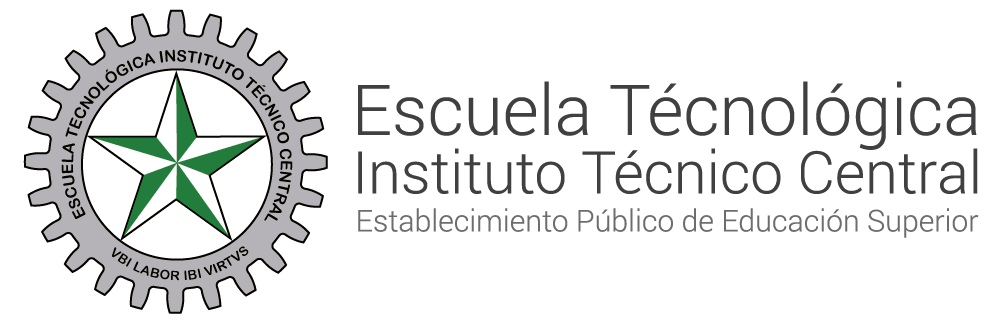

**SISTEMAS DE CONTROL II  **

# **Solución ecuaciones en diferencias**

#### Autor ING. JHEYSON FABIAN VILLAVISAN BUITRAGO MS.c

#### Autores: Jeisson Sierra Aya - Tommy Mancipe Gurierrez

Encontrar la transformada Z y resolver con respecto a la variable de salida $y\left(k\right)$


$$2y\left\lbrack k\right\rbrack -2y\left\lbrack k-1\right\rbrack +y\left\lbrack k-2\right\rbrack =u\left\lbrack k\right\rbrack$$


Asuma condiciones iniciales iguales a cero (0)

## SOLUCIÓN

#### PASO 1 Transformar la ecuación en diferencias al dominio de z mediante la transformada Z.

recordando que por definición, la transformada de Z esta dada por:

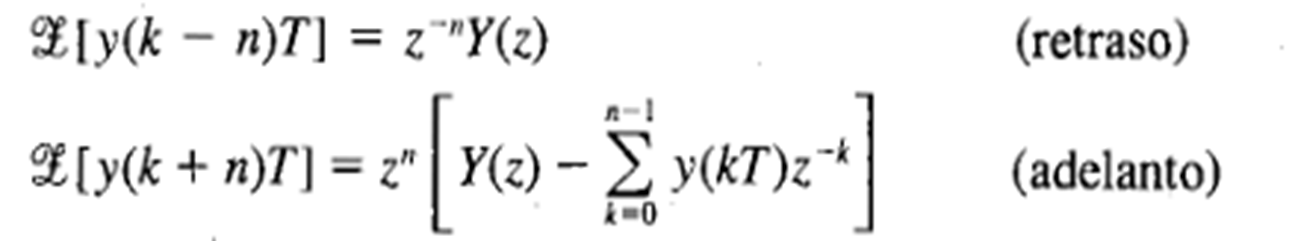

Dividimos la ecuacion en los terminos que la componen y se operan de forma independiente:


$$2y\left\lbrack k\right\rbrack =2Y\left\lbrack z\right\rbrack$$



$$2y\left\lbrack k-1\right\rbrack =2z^{-1} Y\left\lbrack z\right\rbrack$$



$$y\left\lbrack k-2\right\rbrack =z^{-2} Y\left\lbrack z\right\rbrack$$



$$u\left\lbrack k\right\rbrack =\frac{z}{z-1}$$


Luego se reescribiria con la respuesta de cada termino, se obtiene


$$2Y\left\lbrack z\right\rbrack -2z^{-1} Y\left\lbrack z\right\rbrack +z^{-2} Y\left\lbrack z\right\rbrack =\frac{z}{z-1}$$


#### PASO 2 Manipular las ecuaciones algebraicas transformadas y resolverlas para la variable de salida

Factorizando los términos de $Y\left(z\right)$ se obtiene la siguiente expresión:


$$Y\left\lbrack z\right\rbrack \left\lbrace 2-2z^{-1} +z^{-2} \right\rbrace =\frac{z}{z-1}$$


Dado que lo que nos interesa es obtener el comportamiento de $y\left\lbrack k\right\rbrack$ en el dominio del tiempo discreto, procedemos a despejar la función en términos de $Y\left\lbrack z\right\rbrack$ .

Luego del despeje para efectos de quitar complejidad a la expresion, se multiplica en el numerador y el denominador con el inverso del exponente mas alto de z; $z^2$


$$Y\left\lbrack z\right\rbrack =\frac{z}{\left(z-1\right)}*\frac{1}{\left(2-2z^{-1} +z^{-2} \right)}*\frac{z^2 }{z^2 }$$


Daria como resultado:


$$Y\left\lbrack z\right\rbrack =\frac{z}{\left(z-1\right)}*\frac{z^2 }{\left(2z^2 -2z+1\right)}$$


Se opera la otra parte de la fraccion:


$$Y\left\lbrack z\right\rbrack =\frac{z}{\left(z-1\right)}*\frac{z^2 }{\left(2z^2 -2z+1\right)}$$


Finalmente al operar se optendia la expresion:


$$Y\left\lbrack z\right\rbrack =\frac{z^3 }{\left(z-1\right)\left(2z^2 -2z+1\right)}$$


#### PASO 3 Realizar la expansión en fracciones parciales de la ecuación algebraica transformada.

A continuación vamos a representar la función utilizando matlab:

syms z
numerator = [1 0 0 0];
a_0=[1 -1];
a_1=[2 -2 1];
denominator = conv(a_0,a_1);
ts=1;
Y_z = tf(numerator,denominator,ts)


Y_z =
 
            z^3
  -----------------------
  2 z^3 - 4 z^2 + 3 z - 1
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


Ahora procedemos a utilizar la función "residuez" con el objetivo de obtener la descomposición en fracciones parciales de la función de transferencia:

[r,p,k] = residuez(numerator,denominator)

r =    1.0000 + 0.0000i
  -0.2500 - 0.2500i
  -0.2500 + 0.2500i


p =    1.0000 + 0.0000i
   0.5000 + 0.5000i
   0.5000 - 0.5000i


k = 0


$$Y\left\lbrack z\right\rbrack =\frac{1}{z-1}+\frac{-0\ldotp 25i}{z-\left(0\ldotp 5+0\ldotp 5i\right)}+\frac{0\ldotp 25i}{z-\left(0\ldotp 5-0\ldotp 5i\right)}$$


La documentación de matlab nos dice que la fracción parcial se puede reescribir de la siguiente manera:

Y_z_fract=(simplify((r(1)/(1-(p(1)*z^(-1)))))+collect((r(2)/(1-(p(2)*z^(-1)))))+collect((r(3)/(1-(p(3)*z^(-1)))))+k)

$$Y\_z\_fract = k+\frac{z}{z-1}+\frac{\left(-1-\mathrm{i}\right)\,z^{2}+z}{4\,z^{2}-4\,z+2}+\frac{\left(-1+\mathrm{i}\right)\,z^{2}+z}{4\,z^{2}-4\,z+2}$$

#### PASO 4

A continuación obtendremos la transformada inversa Z

### 
$$Y\left\lbrack z\right\rbrack =\frac{z}{z-1}+\frac{z\left(\frac{633318697598977}{2535301200456458802993406410752}-\frac{1i}{2}\right)}{2z-\left(1+i\right)}+\frac{z\left(\frac{633318697598977}{2535301200456458802993406410752}-\frac{1i}{2}\right)}{2z-\left(1+i\right)}$$


syms k;
(iztrans(Y_z_fract,z,k))

$$ans = k\,\delta_{k,0}+1+\frac{{\left(-1\right)}^{k}\,2^{1-k}\,{\left(-1-\mathrm{i}\right)}^{k-1}\,\mathrm{i}}{4}-\frac{{\left(-1\right)}^{k}\,2^{1-k}\,{\left(-1+\mathrm{i}\right)}^{k-1}\,\mathrm{i}}{4}$$